subject = 'mpx';
num = 1;
a = [subject '_paramatrix_' int2str(num)];
fprintf(a);

mpx_paramatrix_1

load([subject '_paramatrix_' int2str(num)]);
paramatrix(:,7) = zeros(length(paramatrix(:,1)),1);
for i = 1:length(paramatrix(:,1))
    fprintf('(%d,2) = %d,(%d,6) = %d\n',i,paramatrix(i,2),i,paramatrix(i,6));
    if (paramatrix(i,2)==-1) && (paramatrix(i,6)==1) 
        paramatrix(i,7) = 1;
    else 
        paramatrix(i,7) = 0;
    end
end

(1,2) = -1,(1,6) = 1
(2,2) = -1,(2,6) = 1
(3,2) = -1,(3,6) = 1
(4,2) = 1,(4,6) = 0
(5,2) = -1,(5,6) = 1
(6,2) = 1,(6,6) = 1
(7,2) = 1,(7,6) = 1
(8,2) = 1,(8,6) = 1
(9,2) = -1,(9,6) = 1
(10,2) = -1,(10,6) = 1
(11,2) = -1,(11,6) = 1
(12,2) = 1,(12,6) = 1
(13,2) = -1,(13,6) = 1
(14,2) = 1,(14,6) = 1
(15,2) = -1,(15,6) = 1
(16,2) = -1,(16,6) = 1
(17,2) = -1,(17,6) = 1
(18,2) = -1,(18,6) = 1
(19,2) = 1,(19,6) = 1
(20,2) = 1,(20,6) = 1


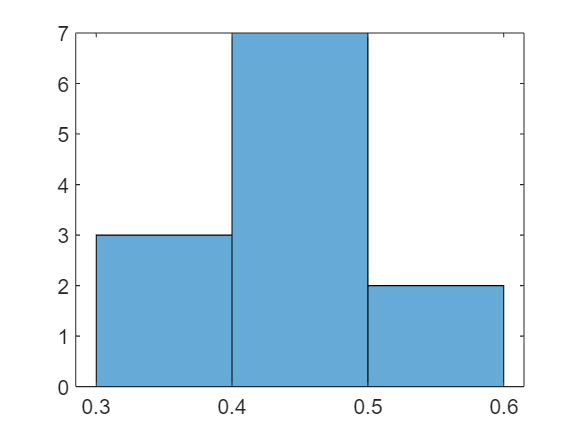


data = paramatrix(paramatrix(:,7)==1,5);
histogram(data);

fprintf('mean = %.4f\n',mean(data));

mean = 0.4634


fprintf('var = %.4f\n',var(data));

var = 0.0039
